% Definir variables simbólicas
syms dx dy

% Coordenadas de los puntos A, B, y C
ax = 150;
ay = 400;
bx = 350;
by = 350;
cx = 250;
cy = 375;

% Distancia AB
AB = sqrt((bx - ax)^2 + (by - ay)^2);

% Distancia CD
CD = sqrt((dx - cx)^2 + (dy - cy)^2);

% Condición 1: Relación entre las distancias CD / AB = 2.43
eq1 = CD / AB == 2.43;

% Condición 2: Perpendicularidad (producto punto = 0)
AB_vector = [bx - ax, by - ay];
CD_vector = [dx - cx, dy - cy];
eq2 = AB_vector(1) * CD_vector(1) + AB_vector(2) * CD_vector(2) == 0;

% Resolver el sistema de ecuaciones
solutions = solve([eq1, eq2], [dx, dy]);

% Mostrar las soluciones
dx_solution = double(solutions.dx);
dy_solution = double(solutions.dy);

disp("Soluciones para dx:");

Soluciones para dx:


disp(dx_solution);

  128.5000
  371.5000




disp("Soluciones para dy:");

Soluciones para dy:


disp(dy_solution);

  -111
   861





syms x m
expr = (x + 3*m - (3*sqrt(1-m^2)*1i)) * ...
       (x + 3*m + (3*sqrt(1-m^2)*1i))

$$expr = \left(3\,m+x-3\,\sqrt{1-m^{2}}\,\mathrm{i}\right)\,\left(3\,m+x+3\,\sqrt{1-m^{2}}\,\mathrm{i}\right)$$


       (x + 3*m - (3*sqrt(1-m^2)*1i)) * ...
       (x + 3*m + (3*sqrt(1-m^2)*1i))

$$ans = \left(3\,m+x-3\,\sqrt{1-m^{2}}\,\mathrm{i}\right)\,\left(3\,m+x+3\,\sqrt{1-m^{2}}\,\mathrm{i}\right)$$

simplified_expr = expand(expr);
disp(simplified_expr);

$$x^{2}+6\,m\,x+9$$

punto 3

syms s t
% Definimos la función de transferencia
num = [18 54 81];
den = [1 6 18 54 81];
G = tf(num, den);

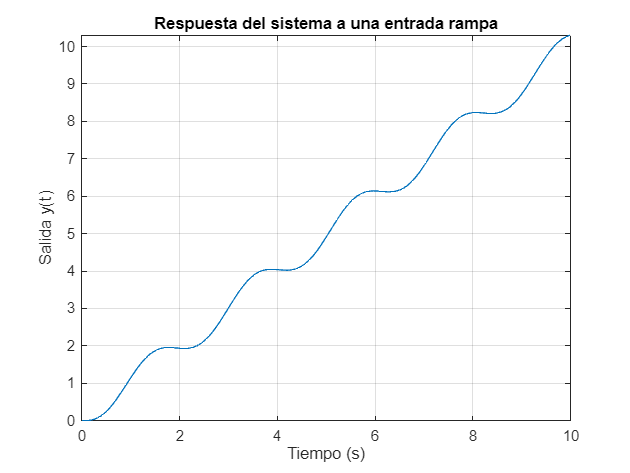

% Definimos la entrada rampa
Ramp = tf(1, [1 0 0]);

% Multiplicamos la función de transferencia del sistema por la entrada
Sal = G * Ramp;

% Obtenemos la transformada inversa de Laplace para la salida
[ns, ds] = tfdata(Sal, 'v'); % Extraemos los coeficientes
Y_s = poly2sym(ns, s) / poly2sym(ds, s); % Expresamos Sal en términos simbólicos
y_t = ilaplace(Y_s); % Transformada inversa de Laplace

% Graficamos la salida
fplot(y_t, [0, 10]); % Intervalo de tiempo de 0 a 10 segundos
grid on;
title('Respuesta del sistema a una entrada rampa');
xlabel('Tiempo (s)');
ylabel('Salida y(t)');

% Extraer datos
time_salidas = salidas(:, 1);

Unrecognized function or variable 'salidas'.

signal_salidas = salidas(:, 2);

time_lineal = lineal(:, 1);
signal_error = lineal(:, 2);  % Error e(t)

% Figura con subgráficas
figure;
plot(time_lineal, signal_error, 'b', 'LineWidth', 1); % Error e(t)
hold on;
plot(time_lineal, signal_salidas, 'r', 'LineWidth', 1); % Señal opuesta (si es necesaria)
grid on;
set(gca, 'FontSize', 14, 'FontName', 'Times');
xlabel('Tiempo [s]', 'Interpreter', 'latex', 'FontSize', 14);
ylabel('Valor', 'Interpreter', 'latex', 'FontSize', 14);
legend({'Con $d(t)$', 'Sin $d(t)$'}, 'FontSize', 12, 'Interpreter', 'latex');
title('Respuesta ante referencia $r(t) = u(t)$ con y sin saturacion ($d(t) = u(t)$)', 'Interpreter', 'latex', 'FontSize', 14);
ylim([0, 1.6]);
xlim([0, 10]);

